[command, via_point_task_all] = readVariable("robot_command_v0.txt", "via_points_info_v0.txt");
[alert, via_point_joint] = task2jointConversion(via_point_task_all);


[selected_via_point_joint, all_via_point_joint, cost] = optimalPath(via_point_joint, "shortest_path");

min_cost = 5.2639

min_idx = 1

v_max = 1.75;
a_max = 0.5;
[C,t_i,T,alert_traj] = coefficientGen(selected_via_point_joint, v_max, a_max)

C = C(:,:,1) =

         0         0         0         0         0         0
   -1.7521         0         0    0.0256   -0.0095    0.0010
    3.1416         0         0   -0.2157    0.0806   -0.0080


C(:,:,2) =

         0         0         0         0         0         0
   -1.5867         0         0    0.2991   -0.1550    0.0214
    1.7453         0         0    0.2517   -0.1304    0.0180


C(:,:,3) =

         0         0         0    0.1438   -0.0358    0.0024
   -0.8607         0         0         0         0         0
    2.3562         0         0         0         0         0


t_i =          0    4.0153    6.9107


T = 12.9337

alert_traj = 0

[C_t,t_i,T] = coefficientGenTask(selected_via_point_joint,t_i,T)

C_t = C_t(:,:,1) =

    0.3500         0         0    0.0380   -0.0142    0.0014
         0         0         0         0         0         0
    0.3500         0         0   -0.0319    0.0119   -0.0012


C_t(:,:,2) =

    0.5962         0         0   -0.1376    0.0713   -0.0098
         0         0         0         0         0         0
    0.1434         0         0    0.1725   -0.0894    0.0123


C_t(:,:,3) =

    0.2621         0         0   -0.0240    0.0060   -0.0004
         0         0         0   -0.0000    0.0000   -0.0000
    0.5621         0         0         0         0         0


t_i =          0    4.0153    6.9107


T = 12.9337

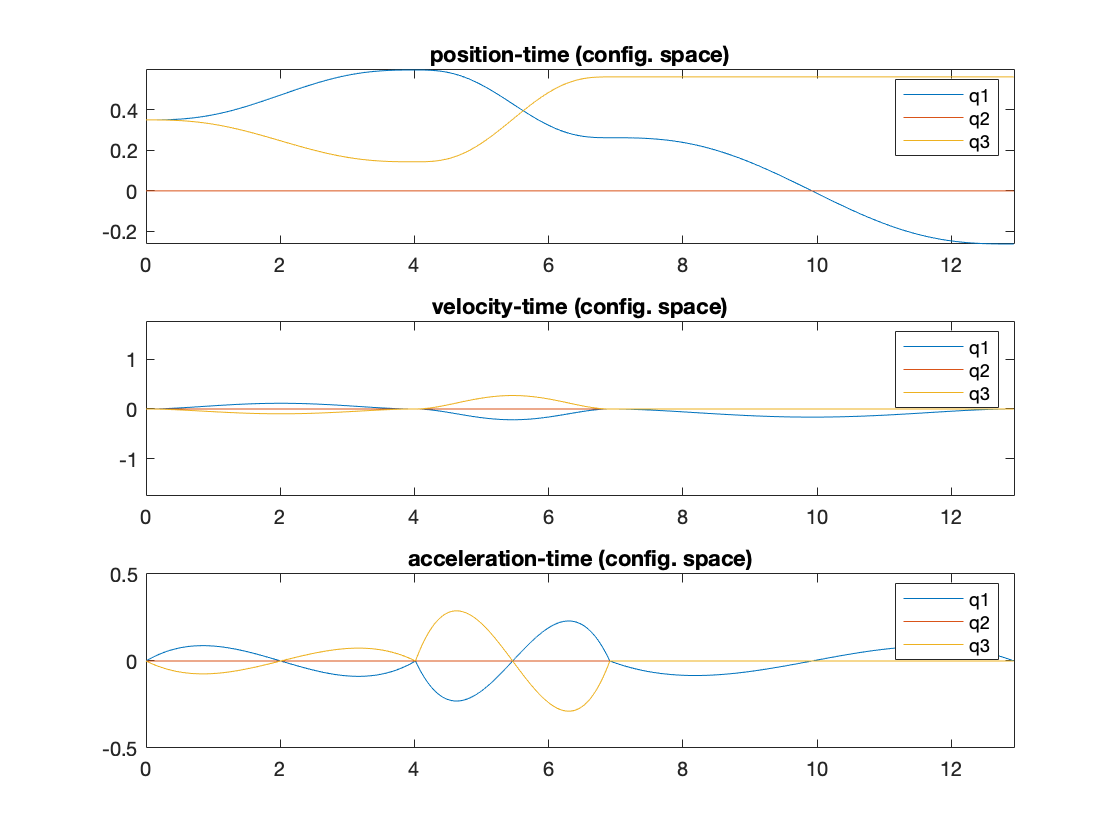

sampling = 1e-2; t = (0:sampling:T); %linspace(0,T,100+1);
p = [];
v = [];
a = [];

for i = 1:numel(t)
    k = discretize(t(i),[t_i T]);
   [p_j,v_j,a_j] = polyTrajEval(t(i),C_t(:,:,k),t_i(k));

    p = [p p_j];
    v = [v v_j];
    a = [a a_j];

end

subplot(3,1,1)
plot(t, p)
title('position-time (task space)')
legend({'q1','q2','q3'})
xlim([0 T])

subplot(3,1,2)
plot(t, v)
title('velocity-time (task space)')
legend({'q1','q2','q3'})
xlim([0 T]); ylim([-v_max v_max])

subplot(3,1,3)
plot(t, a)
title('acceleration-time (task space)')
legend({'q1','q2','q3'})
xlim([0 T]); ylim([-a_max a_max])